# Substitution

A thorough understanding of the integral as an antiderivative can only take you so far. Just as with derivatives, there are integration rules that can be built through the combination of functions as well. The method of substitution that will be discussed in this live script applies to nearly every integral you will ever calculate. In fact, you will likely forget that you are even applying it in some cases because it will become so natural to use!

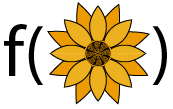

The method of substitution allows you to replace a complicated integral with a simpler one.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

clear
 

## Visualizing changing variables

clear x
syms x

It can be counterintuitive to visualize how a change of variables affects your function or the resulting integral. Use this to investigate different combinations of functions. 

### Set up the functions to use

f = @(x)sin(x);
g = @(x)log(x+5.001);

Choose a left endpoint $a$ and a right endpoint $b$ such that $a \leq x \leq b$:

a =-3.4; b = 2.1;
if a > b
    warning("This code assumes a<b. Please set your values accordingly.")
end
tVals = linspace(min(a,b),max(a,b),10000);
gVals = double(g(tVals));
fVals = double(f(gVals));

Visualize the graph as $f(g(x))$ vs $x$ or $f(g(x))$ vs $g(x)$:

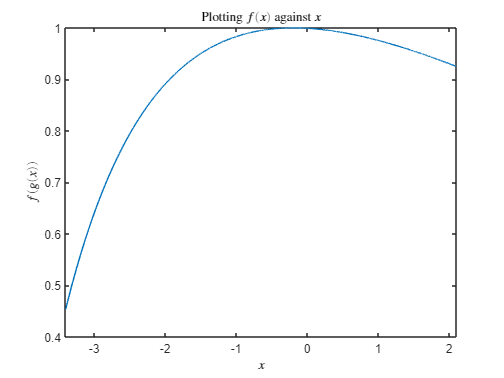

xOrg = "indX";
if xOrg == "indX"
    displayXvsF = 1;
else
    displayXvsF = 0;
end
clear p2
fig1 = figure;
p1 = plot(gVals,fVals);
ax = p1.Parent;
ylabel(ax,"$f(g(x))$","Interpreter","latex")

if displayXvsF
    p1.XData = tVals;
    ax.XLim = [tVals(1) tVals(end)];
    title(ax,"Plotting $f(x)$ against $x$","Interpreter","latex")
    xlabel(ax,"$x$","Interpreter","latex")
else
    p1.XData = gVals;
    ax.XLim = [min(gVals) max(gVals)];
    title(ax,"Plotting $f(x)$ against $g(x)$","Interpreter","latex")
    xlabel(ax,"$g(x)$","Interpreter","latex")
end

Choose a step size and an initial point:

The step size shown is dx = 0.75 and the initial point is x_0=1.1.


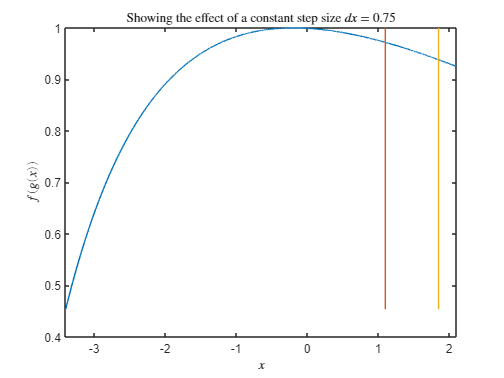

step = 0.75; x0 = 1.1;
 
flag = "xdx";
y0 = double(f(g(x0)));
g0 = double(g(x0));
g1 = g0+step;
g2 = double(g(x0+step));
yM = max(fVals);
ym = min(fVals);

switch flag
    case "gdx"
        disp("The step size shown is dg = "+step+" and the initial point is g_0="+g0+".")
        if (g0+step > max(gVals)) || (g0+step < min(gVals))
            warning("This step size moves outside the domain window shown.")
        end
        title(ax,"Showing the effect of the chosen step size $dg =$"+step,"Interpreter","latex")
        p1.XData = gVals;
        ax.XLim = [min(gVals) max(gVals)];
        xlabel(ax,"$g(x)$","Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [g0 g0];
            p2(2).XData = [g1 g1];
        else
            hold on
            yM = max(fVals);
            ym = min(fVals);
            p2 = plot(ax,[g0 g0],[ym yM],[g1 g1],[ym yM]);
            hold off
        end
    case "xdx"
        disp("The step size shown is dx = "+step+" and the initial point is x_0="+x0+".") %#ok<*UNRCH>
        if (x0+step > max(tVals)) || (x0+step < min(tVals))
            warning("This step size moves outside the domain window shown.")
        end
        p1.XData = tVals;
        ax.XLim = [tVals(1) tVals(end)];
        t0 = x0;
        t1 = x0+step;
        y1 = double(f(g(x0+step)));
        xlabel(ax,"$x$","Interpreter","latex")
        title(ax,"Showing the effect of a constant step size $dx = $"+step,"Interpreter","latex")
        if exist("p2","var")
            p2(1).XData = [t0 t0];
            p2(2).XData = [t1 t1];
        else
            hold on
            p2 = plot(ax,[t0 t0],[ym yM],[t1 t1],[ym yM]);
            hold off
        end
    case "gdg"
        disp("The step size is dx ="+step+".")
        disp("Therefore the step size shown is dg = "+(g2-g0)+" and the initial point is g_0="+g0+".")
        if ~isreal(g2)
            warning("This value is outside the real domain of g. Please choose a different step size.")
        else
            if (g2 > max(gVals)) || (g2 < min(gVals))
                warning("This step size moves outside the domain window shown.")
            end
            title(ax,"Showing the effect of the substitution on the step size $dg = g(x_0+dx)-g(x_0)$","Interpreter","latex")
            p1.XData = gVals;
            ax.XLim = [min(gVals) max(gVals)];
            xlabel(ax,"$g(x)$","Interpreter","latex")
            if exist("p2","var")
                p2(1).XData = [g0 g0];
                p2(2).XData = [g2 g2];
            else
                hold on
                p2 = plot(ax,[g0 g0],[ym yM],[g2 g2],[ym yM]);
                hold off
            end
        end
end

### Covering the entire region by intervals

Set up the functions and the bounds to use. 

clear f g p3
syms x
f(x) = sin(x); % sin(x) 
g(x) = 1/(1+x^2); % 1/(1+x^2) work well, used to use x^4
 
a =-1.2; b = 6.9;

How many intervals?

numIntervals =73;
step = (b-a)/numIntervals;
if step < 0
    tVals = linspace(max(a,b),min(a,b),ceil(1000/numIntervals)*numIntervals);
    stepsize = ceil(1000/numIntervals);
else
    tVals = linspace(min(a,b),max(a,b),ceil(1000/numIntervals)*numIntervals);
    stepsize = ceil(1000/numIntervals);
end
gVals = double(g(tVals));
fVals = double(f(gVals));
dgFunc = diff(g,x);
dg = dgFunc(x)*step;
numSteps = length(tVals);
p3 = plot(gVals,fVals);
ax3 = p3.Parent;
title(ax3,"Show the signed area between $f(g(x))$ and the $g(x)$-axis","Interpreter","latex")
hold on
xlabel(ax3,"g(x)")
ylabel(ax3,"f(g(x))")
areaGrp = showPosNegArea(fVals,gVals,0,2,0);

#### Animate Visualization by Original or Substitution-size Steps

First, show the positions of intervals defined by a constant step size $dg$, then subdivide the same region by intervals defined by a constant step size $dx$ under the map $g(x_k+dx) = g(a+kdx)$ where $x_k$ is the initial point of the $k^{\text{th}}$ interval. Equivalently, $x = a$ is the lower bound of the corresponding interval.  

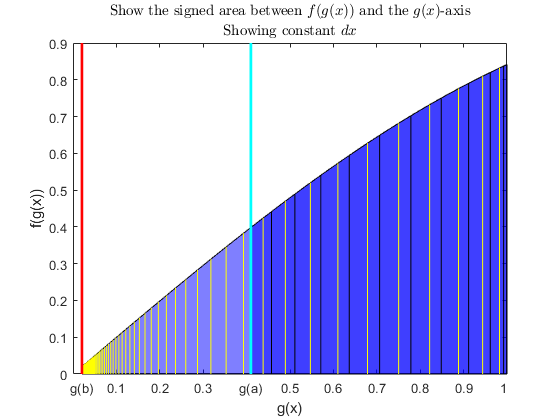

idx = 1:stepsize:length(tVals);
constdgDomain = linspace(gVals(1),gVals(end),length(idx));
constfVals = double(f(constdgDomain));
runAnimateStripes = true;
if runAnimateStripes
    delete(ax3.Children(1:end-2))
    dxGrp = hggroup;
    dgGrp = hggroup;
    subtitle("With constant $dg$","Interpreter","latex")
    dgGrp = animateStripes(ax3,constdgDomain,constfVals,1:length(idx),dgGrp,1);
    dgGrp = addStartEnd(ax3,constdgDomain,dgGrp);
    dgGrp.Visible = "off";
    subtitle("With constant $dx$","Interpreter","latex")
    dxGrp = animateStripes(ax3,gVals,fVals,idx,dxGrp,1);
    dxGrp = addStartEnd(ax3,gVals,dxGrp);
    hold off
else
    dxGrp = hggroup;
    dgGrp = hggroup;
    dgGrp = animateStripes(ax3,constdgDomain,constfVals,1:length(idx),dgGrp,0);
    dgGrp.Visible = "off";
    subtitle("Showing constant $dx$","Interpreter","latex")
    dxGrp = animateStripes(ax3,gVals,fVals,idx,dxGrp,0);
    hold off
end
setXTicks(ax3,[gVals(1) gVals(end)],["g(a)" "g(b)"])

#### Show Only One Set of Steps

If the checkbox is selected, then the plot shows the region subdivided into constant-size intervals $dg$. If the checkbox is not selected, then the plot shows the region subdivided into constant-size intervals $dx$. In the latter case, the plotted interval ends occur after lengths $dg = g'(x)dx$. Because this depends on the value of $g'(x)$ it can be a linear transformation, but it can also be highly nonlinear. 

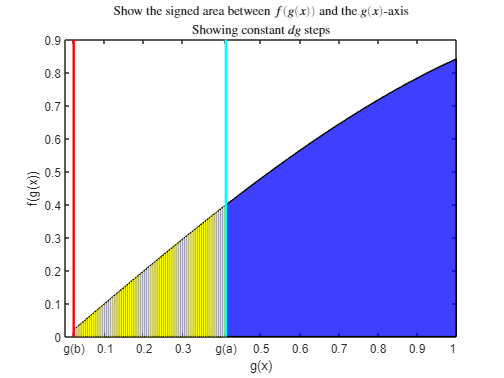

flag = true;
if flag
    dgGrp.Visible = "on";
    dxGrp.Visible = "off";
    subtitle("Showing constant $dg$ steps","Interpreter","latex")
else
    dgGrp.Visible = "off";
    dxGrp.Visible = "on";
    subtitle("Showing constant $dx$ steps","Interpreter","latex")
end

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

function [posRegs,negRegs,allOrderedRegs] = findSignSwitchIndexes(fVals,dVals,f0)
% fVals is a vector of doubles to be compared to a constant f0 at
% points given by dVals, a same-sized vector of doubles.
% Each nonnegative/nonpositive region is a row in posRegs/negRegs, respectively
% The first and last columns are flags (1/0) indicating (yes/no) need for
% interpolation at the beginning/end of the region
% The second column is the index into fVals/dVals of the first pair in that region
% The third column is the index into fVals/dVals of the last pair in that region
% If there are no fVals/dVals pairs in the region the second and third
% column will contain NaN
% allOrderedRegs combines posRegs and negRegs with a fifth column that
% tracks the sign (1 for positive, -1 for negative) in the order that they
% occur moving through dVals

ddVals = dVals(2:end)-dVals(1:end-1);

posDU = ddVals > 0;
zeroDU = ddVals == 0;
negDU = ones(size(ddVals))-posDU-zeroDU;

posF = fVals>=f0;
negF = fVals<=f0;

posPosVals = (posDU + posF(1:end-1) + posF(2:end))==3;
negNegVals = (negDU + negF(1:end-1) + negF(2:end))==3;
allPosVals = posPosVals + negNegVals;
startPosRegIdx = find((allPosVals - [0 allPosVals(1:end-1)])==1);
endPosRegIdx = find(([allPosVals(2:end) 0] - allPosVals)==-1);
if size(startPosRegIdx) ~= size(endPosRegIdx)
    ME = MException("IndexFinder:PairFailure","Unmatched start/end regions");
    throw(ME)
end
posRegs = zeros([length(startPosRegIdx),4]);
posRegs(:,2) = startPosRegIdx';
posRegs(:,3) = endPosRegIdx';

posNegVals = (posDU + negF(1:end-1) + negF(2:end))==3;
negPosVals = (negDU + posF(1:end-1) + posF(2:end))==3;
allNegVals = posNegVals + negPosVals;
startNegRegIdx = find((allNegVals - [0 allNegVals(1:end-1)])==1);
endNegRegIdx = find(([allNegVals(2:end) 0] - allNegVals)==-1);
if size(startNegRegIdx) ~= size(endNegRegIdx)
    ME = MException("IndexFinder:PairFailure","Unmatched start/end regions");
    throw(ME)
end
negRegs = zeros([length(startNegRegIdx),4]);
negRegs(:,2) = startNegRegIdx';
negRegs(:,3) = endNegRegIdx';

allZeroVals = zeroDU;

regIdentified = allPosVals + allNegVals + allZeroVals;

interpIdx = find(regIdentified == 0);
for k = 1:length(interpIdx)
    if ismember(interpIdx(k)+1,startPosRegIdx)
        idx = startPosRegIdx==(interpIdx(k)+1);
        posRegs(idx,1) = 1;
    elseif ismember(interpIdx(k)+1,startNegRegIdx)
        idx = startNegRegIdx==(interpIdx(k)+1);
        negRegs(idx,1) = 1;
    elseif (posDU(interpIdx(k)) && posF(interpIdx(k)+1))||(negDU(interpIdx(k)) && negF(interpIdx(k)+1))
        posRegs = [posRegs;1 nan nan 1]; %#ok<AGROW>
    elseif (negDU(interpIdx(k)) && posF(interpIdx(k)+1))||(posDU(interpIdx(k)) && negF(interpIdx(k)+1))
        negRegs = [negRegs;1 nan nan 1]; %#ok<AGROW>
    else
        warning("Unmatched index value tagged for interpolation.")
    end
    if ismember((interpIdx(k)-1),endPosRegIdx)
        idx = endPosRegIdx==(interpIdx(k)-1);
        posRegs(idx,4) = 1;
    elseif ismember((interpIdx(k)-1),endNegRegIdx)
        idx = endNegRegIdx==(interpIdx(k)-1);
        negRegs(idx,4) = 1;
    end
end

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);

allRegs = [posRegs ones([numPosRegs 1]);...
    negRegs -1*ones([numNegRegs 1])];
allOrderedRegs = sortrows(allRegs,2);
end


function xz = findInterpVal(xl,xr,fl,fr,f0)
% findInterpVals takes coordinates of two points (xl,fl) and (xr,fr) and an
% intermediate value f0 between fl and fr and returns the coordinate xz
% estimating where the line between them crosses the value y = f0
if (fr-f0)*(fl-f0)>=0
    ME = MException("InterpVal:IntervalError","f0 ("+f0+") is not between fl ("+fl+") and fr ("+fr+")");
    throw(ME)
end
%% Calculate the slope between (xl,fl) and (xr,fr)
mf = (fr-fl)/(xr-xl);
%% Solving the linear approximation f0 = mf*(xz-xl)+fl for xz
xz = (f0-fl)/mf+xl;

end

function varargout = showPosNegArea(fVals,dVals,f0,overlapsFlag,pnFlag)
%plot(ax,dVals,fVals,"k")
hold on
[posRegs,negRegs,allRegs] = findSignSwitchIndexes(fVals,dVals,f0);
cols = ["b" "r"];

[numPosRegs,~] = size(posRegs);
[numNegRegs,~] = size(negRegs);
[numRegs,~] = size(allRegs);

if overlapsFlag == 1
    alphaVal = 1/ceil(numRegs/2);
elseif overlapsFlag == 2
    alphaVal = .5;
else
    alphaVal = 1;
end

if pnFlag
    posGrp = drawColoredPolys(fVals,dVals,posRegs,numPosRegs,cols(1),f0,alphaVal);
    negGrp = drawColoredPolys(fVals,dVals,negRegs,numNegRegs,cols(2),f0,alphaVal);
    varargout{1} = posGrp;
    varargout{2} = negGrp;
else
    allGrp = drawColoredPolys(fVals,dVals,allRegs,numRegs,cols(1),f0,alphaVal);
    varargout{1} = allGrp;
end

hold off
end

function polyGrp = drawColoredPolys(fVals,dVals,Regs,numRegs,col,f0,alphaVal)
polyGrp = hggroup;
for k = 1:numRegs
    if ~isnan(Regs(k,2)) && ~isnan(Regs(k,3))
        xVals = dVals(Regs(k,2):Regs(k,3)+1);
        yVals = fVals(Regs(k,2):Regs(k,3)+1);
        if Regs(k,1)
            xnew = findInterpVal(dVals(Regs(k,2)-1),xVals(1),...
                fVals(Regs(k,2)-1),yVals(1),f0);
            xVals = [xnew xVals]; %#ok<AGROW>
            yVals = [f0 yVals]; %#ok<AGROW>
        end
        if Regs(k,4)
            xnew = findInterpVal(xVals(end),dVals(Regs(k,3)+2),...
                yVals(end),fVals(Regs(k,3)+2),f0);
            xVals = [xVals xnew]; %#ok<AGROW>
            yVals = [yVals f0]; %#ok<AGROW>
        end
        x = [xVals flip(xVals)];
        y = [f0*ones(size(yVals)) flip(yVals)];
        patch(x,y,col,"FaceAlpha",alphaVal,"Parent",polyGrp);
        pause(.1)
    end
end
end

function lineGroup = addStartEnd(ax,x,lineGroup)
plot(ax,[x(end) x(end)],ax.YLim,"r-","LineWidth",2,"Parent",lineGroup);
plot(ax,[x(1) x(1)],ax.YLim,"c-","LineWidth",2,"Parent",lineGroup);
end

function lineGroup = animateStripes(ax,x,y,idx,lineGroup,flag)
% x and y are the same length, so this is just creating and adding to
% the relevant lineGroup collection of plotted lines at the index values
% given by idx
% if the flag is set, display as animation
if length(idx)>1
    p = plot(ax,[x(idx(1)) x(idx(1))],[0 y(idx(1))],"k","Parent",lineGroup);
    for k = 2:length(idx)
        copyobj(p,lineGroup)
        if x(idx(k))>= x(idx(k-1))
            lineGroup.Children(k).Color = "k";
        else
            lineGroup.Children(k).Color = "y";
        end
        lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
        lineGroup.Children(k).YData = [0 y(idx(k))];
        if flag
            drawnow
        end
    end
end
lineGroup = addStartEnd(ax,x,lineGroup);
end

function idx = defGStripes(gVals,dgVals) %#ok<DEFNU>
idx = zeros(size(dgVals));
idx(1) = 1;
for k = 1:length(idx)-1
    if dgVals(k) < 0
        try
            idx(k+1) = idx(k) + find(gVals(idx(k)+1:end) <= (gVals(idx(k)) + dgVals(k)),1);
        catch
            warning("Steps continue past the end of the defined domain.")
            idx(k+1) = length(gVals);
        end
    elseif dgVals(k) > 0
        try
            idx(k+1) = idx(k) + find(gVals(idx(k)+1:end) >= (gVals(idx(k)) + dgVals(k)),1);
        catch
            warning("Steps continue past the end of the defined domain.")
            idx(k+1) = length(gVals);
        end
    else
        idx(k+1)=idx(k);
    end
end
end

function setXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end